# **Pràctica 4: Millora dels controladors PID implementats a la pràctica 3**

Les pràctiques de l’assignatura control amb computador consisteixen en l’estudi d’un servomecanisme de posicionament angular controlat per un PC. Les sessions de laboratori P1 i P2 es centren, respectivament, en l’anàlisi experimental de les respostes temporal i freqüencial del sistema. Les sessions P3 i P4 es dediquen al disseny de controladors PID. Finalment, en la pràctica P5 es dissenyaran controladors en camp freqüencial.

**OBJECTIU: Dissenyar un controlador I-P de velocitat de sortida perquè el sistema de llaç tancat tingui un error estacionari nul. Dissenyar un controlador I-PD de la posició de l'eix de sortida per la planta estudiada en les sessions anteriors per tal que el sistema en llaç tancat complixi unes certes especificacions.**

**En aquesta sessió l'estudiant ha de:**

- **Dissenyar un I-P y un I-PD per assignació de pols.**

- **Verificar experimentalment els sistemes de control dissenyats.**

% Canvi entre les dades de l'experiment i els del directori Resultats
% Si voleu utilitzar les dades del directori Resultats = false
% Si voleu utilitzar dades pròpies = true
useExperimentalData = false;

# Exercici 14: Disseny i implementació d'un I-P per assignació de pols.

Com es pot observar a la pràctica 3, en dissenyar un controlador PI amb una planta de primer ordre tenen com a resposta un sistema amb dos pols i un zero. Aquest últim, té un efecte negatiu en la dinàmica del sistema, normalment fent-la una mica més ràpida del desitjat, és per això, que obteníem un petit sobrepuigs. Per eliminar l'efecte del zero, es proposa la següent alternativa d'introduir les accions proporcional i integral.

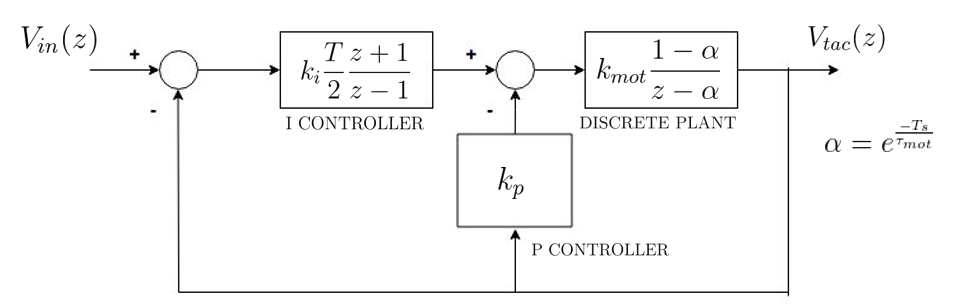

Aquesta estructura pren el nom de controlador IP, i com es pot observar, l'acció integral es realimenta des de l'error, mentre que la part proporcional es realimenta des de la sortida, és per això, que la resposta a un graó del sistema amb un controlador IP serà més suau que la d'un sistema amb un controlador PI. Com s'ha fet al P3, es desitja dissenyar un I-P de control de velocitat que faci que la resposta temporal a una entrada graó no presenti sobrepuigs i que el temps d'establiment (amb el criteri del 2%) sigui de 0.8 segons. Per a la simulació del controlador I-P digital, obrir i executar el model P4_Ex14a.slx. Per a la seva comprovació amb el motor, obrir i executar el model P4_Ex14b.slx.

% planta
K0=0.82;
tau0=0.26;

% Temps de mostratge
Ts=0.01;

% Especificacions
xi=1;
ts_2=0.8; % Temps d'establiment amb el criteri del 2%
Tdes=ts_2/4;
wn=5.8/(xi*ts_2);

% Disseny del controlador
Zdes=exp(-Ts/Tdes);
alpha=exp(-Ts/tau0);
beta=-2*exp(-Ts*xi*wn)*cos(wn*Ts*sqrt(1-xi^2));
gamma=exp(-2*Ts*xi*wn);

Ki_star=(gamma-alpha+beta+(alpha+1))/(2*K0*(1-alpha));
Ki=(2/Ts)*Ki_star;
Kp=((beta+alpha+1)/(K0*(1-alpha)))-Ki_star;

Per a dissenyar el controlador, s'han seguit els següents passos. Primerament, s'ha digitalitzat la planta amb un mantenidor d'ordre zero i s'ha escollit un controlador PI discretitzat mitjançant l'aproximació trapezoïdal.


$$\mathrm{motor}:G\left(z\right)=k_{\mathrm{mot}} \frac{1-\alpha }{z-\alpha }\;\;\;\;\;\;\;\;\;\mathrm{donde}\;\;\;\;\;\;\;\;\;\;\;\;\alpha =e^{-\frac{T_s }{\tau_0 }}$$



$$\mathrm{controlador}\;\mathrm{PI}:\mathrm{PI}\left(z\right)=k_p +k_i \frac{T_s }{2}\frac{z+1}{z-1}=k_p +k_i^* \frac{z+1}{z-1}\;\;\;\;\;\;\mathrm{donde}\;\;\;\;k_i^* =k_i \frac{T_s }{2}$$


En aquest cas, la funció de transferència de llaç tancat:


$$\mathrm{l}c\left(z\right)=\frac{\mathrm{IP}\left(z\right)G\left(z\right)}{1+\mathrm{IP}\left(z\right)G\left(z\right)}=\frac{k_{\textrm{mot}} k_i^* \left(z+1\right)\left(1-\alpha \right)}{\left(z-1\right)\left(z-\alpha \right)+k_{\textrm{mot}} \left(k_p +k_i^* \right)\left(z+\frac{k_i^* -k_p }{k_i^* +k_p }\right)\left(1-\alpha \right)}$$


En el cas del PI la funció de transferència de llaç tancat era:


$$\mathrm{l}c\left(z\right)=\frac{\mathrm{PI}\left(z\right)G\left(z\right)}{1+\mathrm{PI}\left(z\right)G\left(z\right)}=\frac{k_{\textrm{mot}} k_i^* \left(z+\frac{k_i^* -k_p }{k_i^* +k_p }\right)\left(1-\alpha \right)}{\left(z-1\right)\left(z-\alpha \right)+k_{\textrm{mot}} \left(k_p +k_i^* \right)\left(z+\frac{k_i^* -k_p }{k_i^* +k_p }\right)\left(1-\alpha \right)}$$


Com podem observar, en fixar els pols mitjançant els guanys del controlador, automàticament es fixa el zero de llaç tancat. No obstant això, si analitzem el zero de l'arquitectura de l'I-P, podem veure com el zero es fixa en z = -1. 

Com el denominador de llaç tancat és el mateix que l'obtingut en la pràctica 3, les equacions utilitzades per ajustar els paràmetres del controlador són exactament les mateixes que les utilitzades per al controlador PI.


$$\begin{array}{l}
\mathrm{eq}\;\mathrm{real}:z^2 +\left\lbrack \left(k_p +k_i^* \right)k_{\mathrm{mot}} \left(1-\alpha \right)-\left(\alpha +1\right)\right\rbrack z+\alpha +k_{\mathrm{mot}} \left(k_i^* -k_p \right)\left(1-\alpha \right)=0\\
\mathrm{eq}\;\mathrm{ideal}:z^2 -2e^{-T_s \xi \omega_n } \mathrm{cos}\left(\omega_n T_s \sqrt{1-\xi^2 }\right)z+e^{-2T_s \xi \omega_n } 
\end{array}$$


Amb la qual cosa, les equacions de sintonia serien:


$$\begin{array}{l}
k_p =\frac{-\left(-2e^{-T_s \xi \omega_n } \mathrm{cos}\left(\omega_n T_s \sqrt{1-\xi^2 }\right)+e^{-2T_s \xi \omega_n } +1\right)}{T_s \;k_{\mathrm{mot}} \;\left(\alpha -1\right)}\\
k_i =\frac{-2e^{-T_s \xi \omega_n } \mathrm{cos}\left(\omega_n T_s \sqrt{1-\xi^2 }\right)+e^{-2T_s \xi \omega_n } +1}{2{\;k}_{\mathrm{mot}} \;\left(\alpha -1\right)}-\frac{\alpha -2e^{-T_s \xi \omega_n } \mathrm{cos}\left(\omega_n T_s \sqrt{1-\xi^2 }\right)+1}{k_{\mathrm{mot}} \;\left(\alpha -1\right)}
\end{array}$$


Les respostes ideal i real del controlador I-P es poden observar en la següent imatge.

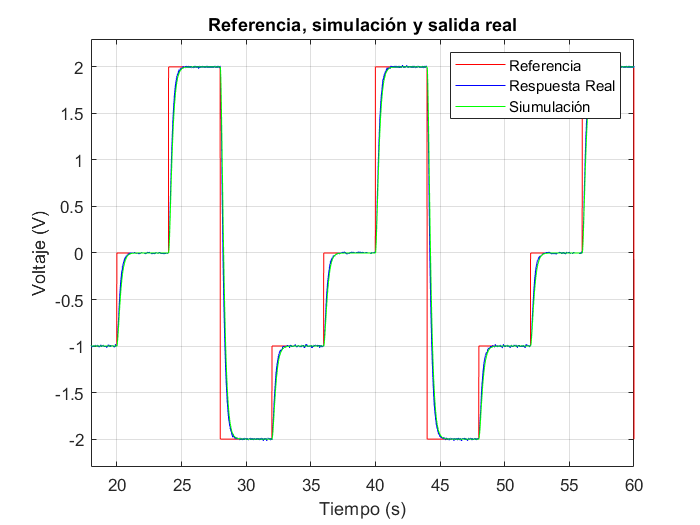

% Dibuixar la resposta del motor
if useExperimentalData
    % Utilitzar Simulink
    addpath([pwd filesep 'IPvel']);
    open IP_experimental.slx;
    run IP_experimental.slx;
else
    FileName   = 'IP_ideal.mat';
    cd('..')
    FolderName = [pwd filesep 'Common' filesep 'Resultados' filesep 'Prac3'];
    File       = fullfile(FolderName, FileName);

    load(File);  
    
    FileName   = 'IP_real.mat';
    FolderName = [pwd filesep 'Common' filesep 'Resultados' filesep 'Prac3'];
    File       = fullfile(FolderName, FileName);
    load(File);  
end

figure
plot(IP_ideal.time,[IP_ideal.signals.values(:,1,:)],'r')
hold on; grid on;
plot(IP_real.time,[IP_real.signals.values(:,2,:)],'b')
plot(IP_ideal.time,[IP_ideal.signals.values(:,2,:)],'g')
xlim([18 60]); ylim([-2.3 2.3]);
xlabel('Temps (s)');
ylabel('Voltatge (V)');
title('Referència, simulació i sortida real');
legend('Referència', 'Resposta Real', 'Siumulación');

Com es pot analitzar, les dues respostes són pràcticament iguals i amb la qual cosa, el sistema real compleix les especificacions desitjades.

# Exercici 15: Disseny i implementació d'un I-PD per assignació de pols.

Com es pot observar a la pràctica 3, en dissenyar un controlador PID amb una planta de segon ordre tenen com a resposta un sistema amb 4 pols i 3 zeros. Per poder dissenyar un controlador PID on es compleixin les especificacions, cal fer dues modificacions principals, la primera, afegir un nou paràmetre al controlador per poder fixar els quatre pols del sistema, i el segon, modificar l'estructura per eliminar l'efecte dels zeros.

Amb la qual cosa, el nou controlador, tindrà la següent estructura:


$$\textrm{controlador}\;\textrm{PI}\mathrm{D}:\mathrm{P}\textrm{ID}\left(z\right)=k_p +k_i^* \frac{z+1}{z-1}+k_d^* \;\frac{z-1}{z+\alpha }\;\;\;\;\textrm{donde}\;\;\;\;k_i^* =k_i \frac{T_s }{2}\;\;y\;k_d^* =\frac{k_d }{T_s }$$


Per eliminar l'efecte dels zeros, es proposa la següent alternativa d'introduir les accions proporcional, integral i derivativa.

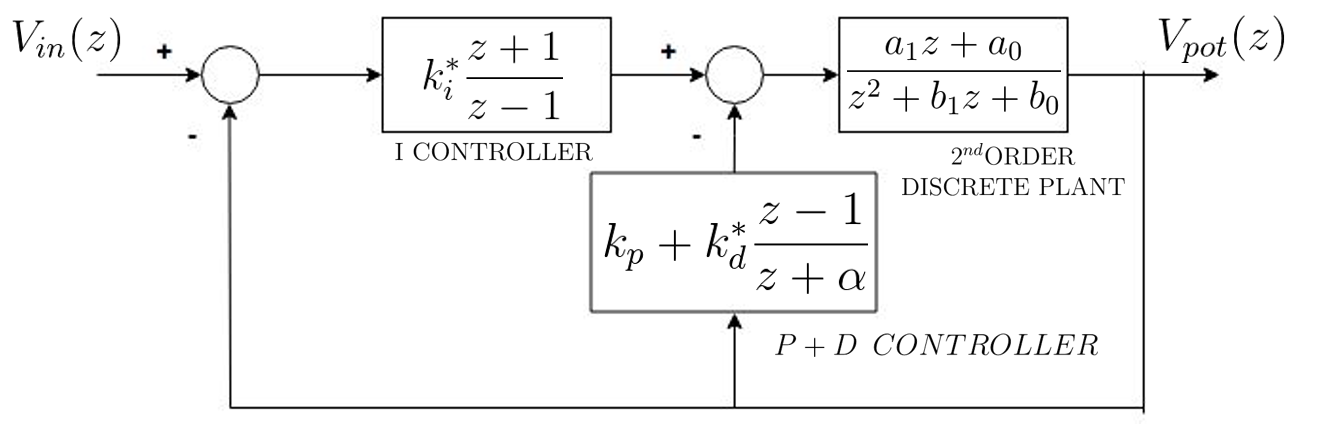

Aquesta estructura pren el nom de controlador I-PD, i com es pot observar, l'acció integral es realimenta des de l'error, mentre que les accions proporcional i derivativa es realimenten des de la sortida.

En aquest exercici es vol dissenyar un I-PD de control de posició que faci que la resposta temporal a una entrada graó presenti un sobrepuig del 80% i una freqüència d'oscil·lació de 0,5 Hz.

Preneu el període de mostratge Ts igual a 0,01s. Determineu el valor de $k_p$,$\;k_i$ y $k_d$ y $\alpha$. 

% Paràmetres de la planta 
K0=0.82/0.017;

xi = 0.0709

tau0=0.26;

wn = 3.1495

N=9;

s1 = -0.2231 + 3.1416i

Kpot=1.62;

s2 = -0.2231 - 3.1416i


% Període de mostratge

p1 = 0.9973 + 0.0313i

Ts=0.01;

p2 = 0.9973 - 0.0313i


% Especificacions de control desitjades

p3 = 0.8000

Sp=80; % Sobrepuig

p4 = 0.8000

Fd=0.5; % freqüència

% Pols de segon ordre continu que compliran les especificacions
wd=2*pi*Fd ;
xi=sqrt((log(Sp/100))^2/(pi^2+log(Sp/100)^2))
wn=wd/ sqrt(1-xi^2)

Nz =          0    0.0016    0.0016


Dz =     1.0000   -1.9623    0.9623


s1=-xi*wn+j*wd
s2=-xi*wn-j*wd
% Pols de segon ordre discret que compliran les especificacions
p1=exp(Ts* s1 )
p2=exp(Ts* s2 )
% Inserir el tercer i quart pol
p3=0.8
p4=0.8
% Funció de transferència discreta de la planta 
Ptas=tf([K0*(1/N)*Kpot],[tau0,1,0]);
Ptaz=c2d(Ptas,Ts,'zoh');

% Coeficients del denominador i enumerador 
[Nz ,Dz]= tfdata(Ptaz,'v')
a1=Nz(2);
a0=Nz(3);
b1=Dz(2);
b0=Dz(3);


alpha = -0.6472

% Definicions de les matrius A i B

c2 = 9.0217

A=[1 a1 0 0; ...

c1 = -17.8623

   b1-1 a0 a1 0; 

c0 = 8.8526

   b0-b1 0 a0 a1; 
  -b0 0 0 a0] ;
b=[-b1+1-p1-p2-p3-p4; 
   -b0+b1+p1*p2-(-p1-p2)*p3-(-p1-p2-p3)*p4; 
   b0-p1*p2*p3-(p1*p2-(-p1-p2)*p3)*p4; 
   p1*p2*p3*p4] ;

kp = 0.3994

ki = 3.4247

% Controlador 

kd = 0.0861

x=inv(A)*b ; 

alpha=x(1)
c2=x(2)
c1=x(3)
c0=x(4)
A2=[1 1 1; alpha-1 alpha+1 -2; -alpha alpha 1];
B2=[c2;c1;c0];

x2=inv(A2)*B2;

kp = x2(1)
ki = (2/Ts)*x2(2)
kd = Ts*x2(3)

En el cas de la pràctica 3 la funció de transferència obtinguda tenia l'estructura següent:


$$\mathrm{cl}\left(z\right)=\frac{a_1 \left(k_p +k_i^* {+k}_d^* \right)z^3 +\left\lbrack a_1 \left(k_i^* -k_p -2k_d^* \right)+a_0 \left(k_p +k_i^* {+k}_d^* \right)\right\rbrack z^2 +\left\lbrack a_1 k_d^* +a_0 \left(k_i^* -k_p -2k_d^* \right)\right\rbrack z+a_0 k_d^* }{z^4 +\left(-1+k_i^* a_1 +b_1 +k_d^* a_1 +k_p a_1 \right)z^3 +\left(-b_1 -k_p a_1 +k_p a_0 +b_0 -2k_d^* a_1 +k_i^* a_0 +k_i^* a_1 +k_d^* a_0 \right)z^2 +\left(k_i^* a_0 -b_0 -2k_d^* a_0 -k_p a_0 +k_d^* a_1 \right)z+k_d^* a_0 }$$


Com podem observar, en fixar els pols mitjançant els guanys del controlador, automàticament es fixen els zeros de llaç tancat. Les expressions dels pols de llaç tancat són els següents:


$$z_{1,2} =\frac{-\left(k_i^* -k_p -2k_d^* \right)\pm \sqrt{-4k_d^* \left(k_p +k_i^* {+k}_d^* \right)+{\left(k_i^* -k_p -2k_d^* \right)}^2 }}{2\left(k_p +k_i^* {+k}_d^* \right)}\;,\;z_3 =\frac{a_0 }{a_1 }$$


En el cas de l'I-PD, la funció de transferència de llaç tancat és la següent:


$$\textrm{cl}\left(z\right)=\frac{k_i^* \left(z+1\right)\left(a_1 z+a_0 \right)\left(z+\alpha \right)}{z^4 +\left(b_1 -1+\alpha +k_i^* a_1 +k_d^* a_1 +k_p a_1 \right)z^3 +\left(b_0 -b_1 +b_1 \alpha -\alpha +k_p a_1 \left(\alpha -1\right)+k_p a_0 -2k_d^* a_1 +k_i^* a_0 +k_i^* a_1 \left(\alpha +1\right)+k_d^* a_0 \right)z^2 +\left(-b_0 +b_0 \alpha -b_1 \alpha +k_p a_0 \left(\alpha -1\right)-k_p a_1 \alpha +k_i^* a_0 \left(\alpha +1\right)+k_i^* a_1 \alpha -2k_d^* a_0 +k_d^* a_1 \right)z+k_d^* a_0 +k_i^* a_0 \alpha -k_p a_0 \alpha -b_0 \alpha }$$


Com podem observar, en aquest cas, els zeros estan fixats en:


$$z_1 =-1,z_2 =-\alpha ,z_3 =\frac{-a_0 }{a_1 }$$


Per obtenir les equacions de sintonia, com podem veure, l'equació obtinguda no és lineal, de manera que substituirem el controlador amb la forma canònica del PID i després els relacionarem amb el PID implementat.

La funció de transferència canònica del PID té la següent forma:


$$\textrm{controlador}\;\textrm{PI}\mathrm{D}:\mathrm{P}\textrm{ID}\left(z\right)=\frac{c_2 z^2 +c_1 z+c_0 }{\left(z-1\right)\left(z+\alpha \right)}$$



$$\textrm{planta}\;\textrm{seg}\textrm{on}\;\textrm{ord}\textrm{re}:G\left(z\right)=\frac{a_{1\;} z+a_0 }{z^2 +b_{1\;} z+b_0 }$$


Amb la qual cosa el denominador de la funció de transferència de llaç tancat amb el controlador canònic pren la forma:


$$\textrm{Den}\left(z\right)=z^4 +\left\lbrack \alpha -1+b_1 +c_2 a_1 \right\rbrack z^3 +\left\lbrack \left(b_1 -1\right)\alpha -b_1 +b_0 +a_1 c_1 +a_0 c_2 \right\rbrack z^2 +\left\lbrack \left(b_0 -b_1 \right)\alpha -b_0 +a_0 c_1 +c_0 a_1 \right\rbrack z+c_0 a_0 -\alpha b_0$$


El polinomi és d'ordre quatre, amb la qual cosa tindrà quatre pols i l'equació característica serà:


$$\begin{array}{l}
\mathrm{Den}\left(z\right)=\left(z-p_1 \right)\left(z-p_2 \right)\left(z-p_3 \right)\left(z-p_4 \right)=z^4 +\left(-p_1 {-p}_2 -p_3 -p_4 \right)z^3 \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;+\left(p_1 p_2 -\left({-p}_1 -p_2 \right)p_3 -\left(-p_1 -p_2 -p_3 \right)p_4 \right)z^2 \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;+\left({-p}_1 p_2 p_3 -\left(p_1 p_2 -\left({-p}_1 -p_2 \right)p_3 \right)p_4 \right)z+p_1 p_2 p_3 p_4 
\end{array}$$


Com és un sistema de quart ordre i 4 incògnites, igualant els coeficients i representant-ho en forma matricial, el sistema en llaç tancat seria:


$$\left\lbrack \begin{array}{cccc}
1 & a_1  & 0 & 0\\
b_1 -1 & a_0  & a_1  & 0\\
b_0 -b_1  & 0 & a_0  & a_1 \\
-b_0  & 0 & 0 & a_0 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\alpha \\
c_2 \\
c_1 \\
c_0 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
1-b_1 -p_1 {-p}_2 -p_3 -p_4 \\
b_1 -b_0 +p_1 p_2 -\left({-p}_1 -p_2 \right)p_3 -\left(-p_1 -p_2 -p_3 \right)p_4 \\
b_0 {-p}_1 p_2 p_3 -\left(p_1 p_2 -\left({-p}_1 -p_2 \right)p_3 \right)p_4 \\
p_1 p_2 p_3 p_4 
\end{array}\right\rbrack$$


Aquest sistema lineal és fàcilment resoluble utilitzant MATLAB. L'equació és $A\;x=b$, on $A$ és una matriu $n\;x\;n$ i $b$ és un vector columna amb $n$ elements, llavors, $x=\mathrm{inv}\left(A\right)·b$.

Finalment, per obtenir els paràmetres $k_p {,\;k}_i \;y\;k_d$ obtindrem la relació entre el nostre controlador i el model canònic.

El nostre controlador, es pot representar també de la següent manera:


$$\mathrm{P}\textrm{ID}\left(z\right)=\frac{\left(k_p +k_i^* +k_d^* \right)z^2 +\left(k_p \left(\alpha -1\right)+k_i^* \left(\alpha +1\right)-2k_d^* \right)z-k_p \alpha +k_i^* \alpha +k_d^* }{\left(z-1\right)\left(z+\alpha \right)}$$


Amb la qual cosa, igualant els coeficients i representant-ho en forma matricial:


$$\left\lbrack \begin{array}{ccc}
1 & 1 & 1\\
\alpha -1 & \alpha +1 & -2\\
-\alpha  & \alpha  & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
k_p \\
k_i^* \\
k_d^* 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
c_2 \\
c_1 \\
c_0 
\end{array}\right\rbrack$$


Com s'ha fet anteriorment, aquest sistema és fàcilment soluble mitjançant MATLAB, sent la solució $x=\textrm{inv}\left(A\right)·b$.

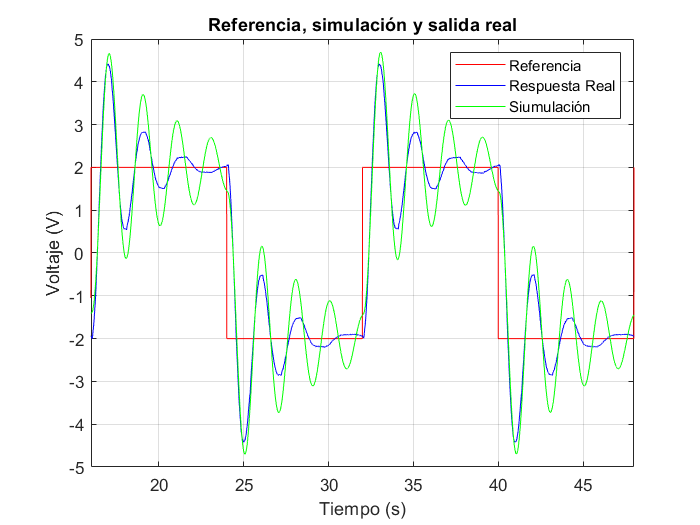

% Dibuixar la resposta del motor
if useExperimentalData
    % Utilitzar Simulink
    addpath([pwd filesep 'IPDpos']);
    open IPD_real_ideal.slx;
    run IPD_real_ideal.slx;
else
    FileName   = 'IPD_real_ideal.mat';
    FolderName = [pwd filesep 'Common' filesep 'Resultados' filesep 'Prac4'];
    File       = fullfile(FolderName, FileName);
    load(File);   
end

figure
plot(IPD_real_ideal.time,[IPD_real_ideal.signals.values(:,1,:)],'r')
hold on; grid on;
plot(IPD_real_ideal.time,[IPD_real_ideal.signals.values(:,2,:)],'b')
plot(IPD_real_ideal.time,[IPD_real_ideal.signals.values(:,3,:)],'g')
xlim([16 48]);
xlabel('Temps (s)');
ylabel('Voltatge (V)');
title('Referència, simulació i sortida real');

legend('Referència', 'Resposta Real', 'Siumulación');

Com podem observar, en aquest cas, les especificacions es compleixen en el cas ideal (simulació amb el model de la planta), però a l'hora de controlar la planta real amb aquesta simulació, podem observar que, tot i que el controlador sigui capaç de controlar la planta, les respostes són força diferents. Això és perquè el model de la planta no representa fidelment la planta real, ja que hi ha dinàmiques no modelades.